Rocket ODE simulation based on the Falcon Heavy Rocket

Staging data:

Payload

payload = struct;

Last Stage

stage1 = struct;
stage1.t    = 50;           %[s]    burn time
stage1.m0   = 433100;       %[kg]   starting mass
stage1.mf   = 2300;         %[kg]   final mass
stage1.T    = 22.82e+06 ;   %[N]    Thrust
stage1.A    = 40;           %[m^2]  front area
stage1.Isp  = 282;          %[s]    specific Impulse

Middle Stage

stage2 = struct;
stage2.t    = 50;           %[s]    burn time
stage2.m0   = 433100;       %[kg]   starting mass
stage2.mf   = 2300;         %[kg]   final mass
stage2.T    = 22.82e+06 ;   %[N]    thrust
stage2.A    = 40;           %[m^2]  front area
stage2.Isp  = 282;          %[s]    specific Impulse

Starting Stage

stage3      = struct;
stage3.t    = 50;           %[s]    burn time
stage3.m0   = 433100;       %[kg]   starting mass
stage3.mf   = 2300;         %[kg]   final mass
stage3.T    = 22.82e+06 ;   %[N]    thrust
stage3.A    = 40;           %[m^2]  front area
stage3.Isp  = 282;          %[s]    specific impulse

Let's get Launching!

First two seconds (streight up):

u0 = [0; pi/2; 0; 0; stage3.m0];
tSpan = [0, 2];

[t1, uOut] = ode45(@(t,u) rocketODEstart(u,stage3),tSpan,u0);

v1      = uOut(:,1); v1(end) 

ans = 87.5040

gamma1  = uOut(:,2); gamma1(end)

ans = 1.5708

x1      = uOut(:,3); x1(end)

ans = 0

h1      = uOut(:,4); h1(end)

ans = 86.9570

m1      = uOut(:,5); m1(end)

ans = 4.1662e+05

t1(end)

ans = 2

Now lets add a tiny change in Angle!

gammaStart = pi/2 - 1/180*pi;
u1 = [v1(end); gammaStart; x1(end); h1(end); m1(end)];
tSpan = [t1(end), stage3.t - t1(end)];

[t2, uOut] = ode45(@(t,u) rocketODE(u,stage3),tSpan,u1);

v2      = uOut(:,1); v2(end)

ans = 5.5293e+03

gamma2  = uOut(:,2); gamma2(end)

ans = 1.5041

x2      = uOut(:,3); x2(end)

ans = 4.6224e+03

h2      = uOut(:,4); h2(end)

ans = 7.3504e+04

m2      = uOut(:,5); m2(end)

ans = 3.7567e+04

t2(end)

ans = 48

Next up: Second Stage!

u2 = [v2(end); gamma2(end); x2(end); h2(end); stage2.m0];
tSpan = [t2(end), stage2.t + t2(end)];

[t3, uOut] = ode45(@(t,u) rocketODE(u,stage2),tSpan,u2);

v3      = uOut(:,1); v3(end)

ans = 1.3443e+04

gamma3  = uOut(:,2); gamma3(end)

ans = 1.5037

x3      = uOut(:,3); x3(end)

ans = 2.9335e+04

h3      = uOut(:,4); h3(end)

ans = 4.5453e+05

m3      = uOut(:,5); m3(end)

ans = 2.1086e+04

t3(end)

ans = 98

And now the third! This time with the steering law included

For this, lets first accumulate the relevatn steering data!

steeringData            = struct;

steeringData = struct with no fields.


steeringData.gamma0     = gamma3(end);
steeringData.tStart     = t3(end);
steeringData.tEnd       = t3(end) + stage1.t;

And now run it!

u3 = [v3(end); gamma3(end); x3(end); h3(end); stage1.m0];
tSpan = [t3(end), stage1.t + t3(end)];


[t4, uOut] = ode45(@(t,u) rocketODEend(u,stage1,t, steeringData),tSpan,u3);

v4      = uOut(:,1); v4(end)

ans = 2.1452e+04

gamma4  = uOut(:,2); gamma4(end)

ans = 1.5037

x4      = uOut(:,3); x4(end)

ans = 2.0014e+05

h4      = uOut(:,4); h4(end)

ans = 1.1715e+06

m4      = uOut(:,5); m4(end)

ans = 2.1086e+04

t4(end)

ans = 148

All the simulations are done! Lets get some plots :)

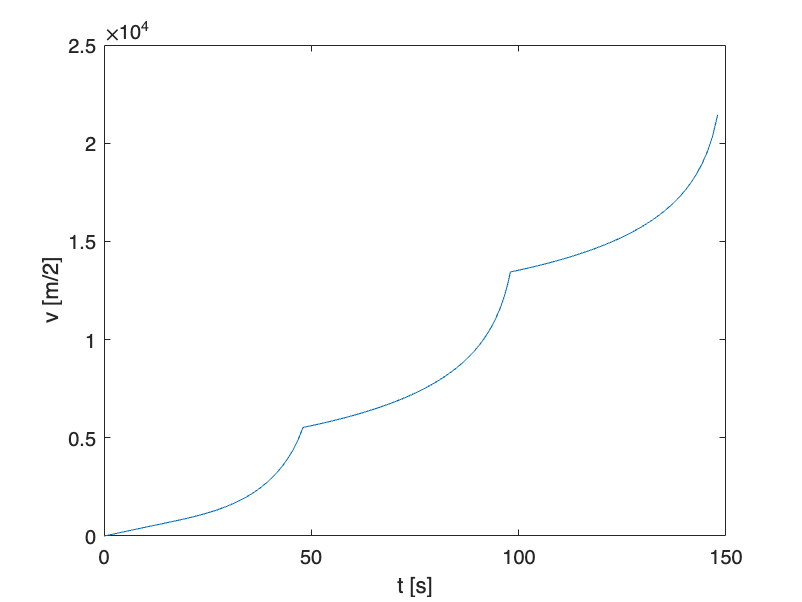

t = [t1; t2; t3; t4];
v = [v1; v2; v3; v4];
x = [x1; x2; x3; x4];
h = [h1; h2; h3; h4];
gamma = [gamma1; gamma2; gamma3; gamma4];
m = [m1; m2; m3; m4];

figure
plot(t, v)
xlabel("t [s]")
ylabel("v [m/2]")

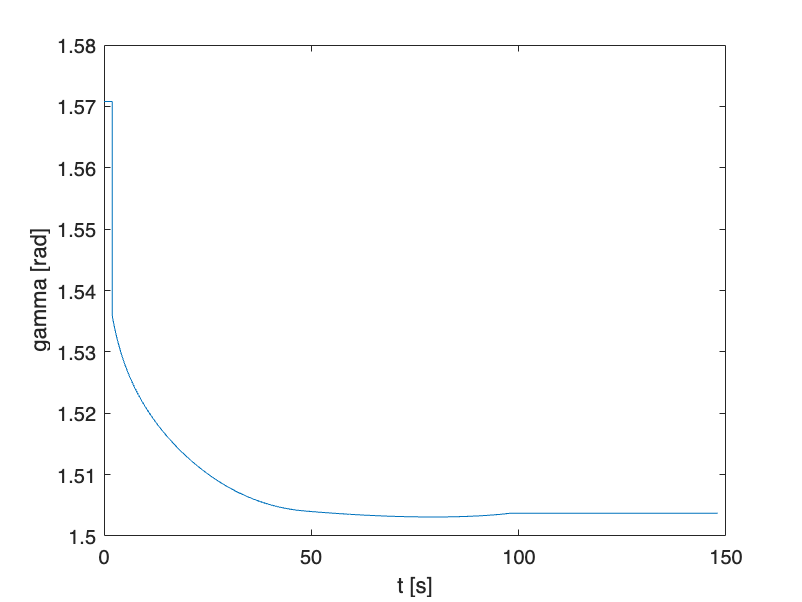


figure
plot(t, gamma)
xlabel("t [s]")
ylabel("gamma [rad]")

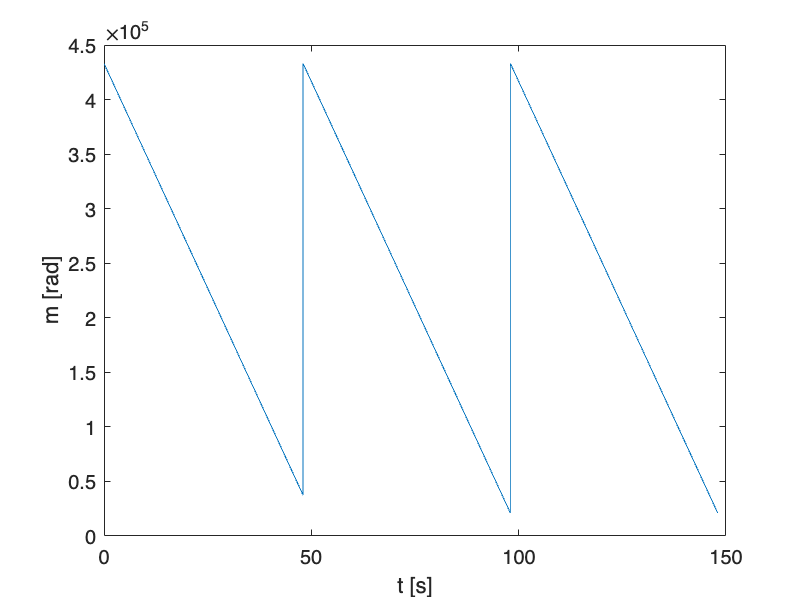


figure
plot(t, m)
xlabel("t [s]")
ylabel("m [rad]")

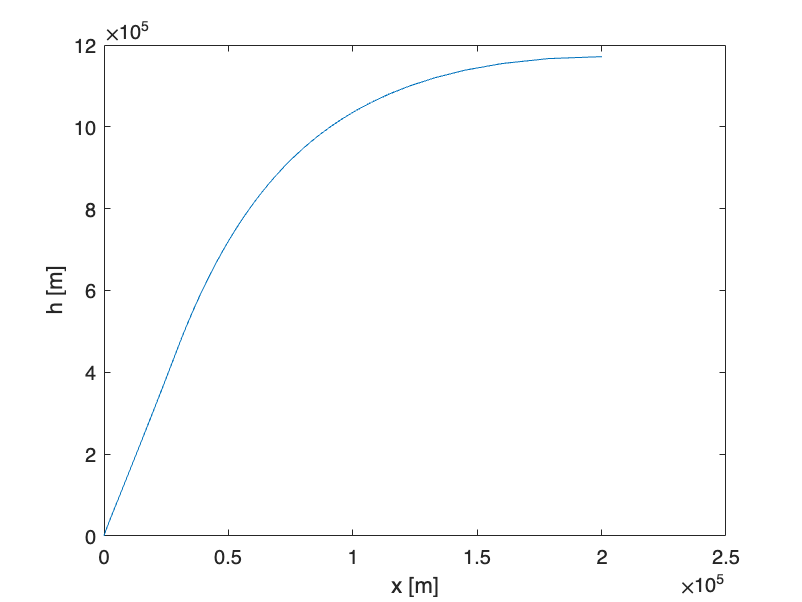


figure
plot(x, h)
xlabel("x [m]")
ylabel("h [m]")